# DSM Solver - Benchmark Problem - Comprehensive

In this run, an arbitary structure is create to compare the result with the commercial software.

clear all

## Definition of the Problem

Define ***Unit***

% { Force_Unit, Length_Unit }
Unit = {'kip', 'ft'}

Unit = 1×2 cell array
    {'kip'}    {'ft'}


Define ***Table of Node***

% i th Row = i th Node
% Row = [ X_Coordinate, Y_Coordinate ]
Node_Table =   [0   0; 
                10  0; 
                20  0; 
                30  0; 
                40  0; 
                0   6; 
                10  6; 
                20  6; 
                30  6];

Define ***Table of Element***

% i th Row = i th Element
% Row = [ Property_Type, Begin_Node_ID, End_Node_ID, Begin_Hinge?, End_Hinge? ]
Element_Table =    [1   1   6   0   0;
                    1   2   7   0   0;
                    1   3   8   0   0;
                    1   4   9   0   0;
                    1   5   9   0   0; 
                    1   6   7   0   1; 
                    1   7   8   0   0;
                    1   8   9   0   0;
                    1   7   3   1   0];

Define ***Property of Element***

% i th Row = i th Property
% Row = [ E, A, I ]
Element_Property = [29000*144 3.54/144 53.8/144^2];

Review ***Initial Graph***

*Element Hinge is shown as a Solid Blue Circle on the End of the Member*

% Size Parameter for Font, Marksize, and Line Width
Size_Parameter = 240 

Size_Parameter = 240

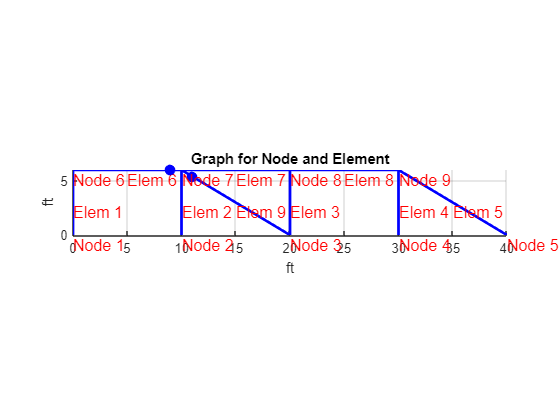


% Plot Initial Graph
Graph_Initial(Node_Table, Element_Table, Unit, Size_Parameter)

Define ***Eccentrial*** ***Boundary Condition on Node***

*Support arbitary direction (not necessary along the direction of global axis).*

*One definition per node only, the program will use the last definition if there is multiple boundary condition on the same node. *

% i th Row = i th Eccential_Boundary_Condition
% [ Node_ID, Restriction_on_Translation_x, Restriction_on_Translation_y, Restriction_on_Rotation_on_z, Angle(deg) ]
Boundary_H =   [1   1   1   1   0; 
                2   1   1   1   0;
                3   1   1   0   0;
                4   1   1   0   0;
                5   1   1   1   0];

Define ***Natural Boundary Condition on Node***

*One definition per node only, the program will use the last definition if there is multiple boundary conditions on the same node. *

% i th Row = i th Natural_Boundary_Condition
% Row = [ Node_ID, F_X, F_Y, M_Z ]
Boundary_Q =    [6  50  0   0];

Define ***Natural Boundary Condtion on Element***

*Support multiple boundary conditions on the same element.*

*Please see the ****Element_Load_Typle_Table**** for the instruction.*

% i th Row = i th Natural_Boundary_Condition
% Row = [ Element_ID, Load_Parameter_1, Load_Parameter_2, Length_Ratio_Parameter_1, Ratio_Parameter_2 ]
Element_Q =    [6   1   40  0   0.2     0.8;
                7   1   20  0   0.5     0.5;
                7   3   10  0   0       0;
                9   3   20  0   0       0;
                8   4   -5  12  0.2     0.3];

Define ***Support Movement***

*Will only be effective only if the associate ****Eccentrail Boundary Condition**** has been defined.*

*One definition per node only, the program will use the last definition if there is multiple boundary conditions on the same node. *

% i th Row = i th Boundary_Movement
% Row = [ Node_ID, U_X, U_Y, Theta_Z ]
Boundary_Movement =     [];

Review ***Completed Graph***

***RED Square and H**** on Node indicate the ****Eccential Boundary Condition on Node***

***Magenta Star and Q**** on Node indicate the ****Natural Boundary Condition on Node (if defined)***

***Magenta EQ**** on Element indicate the ****Natural Boundary Condition on Element***

***Green Pentagram and U**** on Node indicate the ****Support Movement on Node***

***BLUE Solid Circle**** on Element indicate ****Hinge on Element end***

***BLUE Hollow Circle**** on Node indicate ****Global Hinge on Node***

% Check Global Hinge
Global_Hinge = Global_Hinge_Check(Node_Table, Element_Table)

Global_Hinge = 9×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0


Discription =     'RED Square and H on Node indicate the eccential boundary condition on node
     Magenta Star and Q on Node indicate the natural boundary condition on node (if defined)
     Magenta EQ on Element indicate the natural boundary condition on element
     Green Pentagram and U on Node indicate the boundary movement on node
     BLUE Solid Circle on Element indicate hinge on element end
     BLUE Hollow Circle on Node indicate global hinge on node'


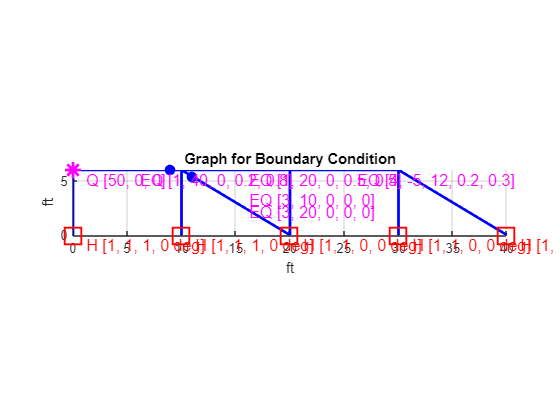


% Plot Completed Graph
Graph_Boundary(Node_Table, Element_Table, Unit, Global_Hinge, Size_Parameter, Boundary_H, Boundary_Q, Element_Q, Boundary_Movement)

## Solution of the Problem

% Assemble Global Stiffness Matrix
K_global = Global_Stiffness_Matrix(Node_Table, Element_Table, Element_Property);

% Evaluate Global Force Vector from Element Load
F_E = Global_Force_Vector(Node_Table, Element_Table, Element_Q);

% Evaluate Global Force Vector from Node Load & Support Movement
[F_Q, F_H] = Global_Boundary_Force_Vector(K_global, Boundary_Q, Boundary_Movement);

% Assemble Special Structural Stiffness Matrix with the Consideration of Arbitary Support Direction
[K_structural_special, F_structural_special, TK_global, Boundary_Restriction_List, Global_Hinge_List] = Boundary_Process(K_global, F_E, F_Q, F_H, Boundary_H, Global_Hinge);

% Compute Structural Displacement on Special Space
U_structural_special = K_structural_special\F_structural_special;

## Stability Check

*Please note that a solution can exist if within the eigen space even if the structure is unstable*

% Check the Stability of the Problem
Stability = Stability_Check(K_structural_special)

Stability = 'Structure is stable'

## Result of the Problem

% Recover Global Displacement
U_global = Global_Displacement(U_structural_special, TK_global, Boundary_Restriction_List, Global_Hinge_List, Boundary_Movement)

U_global =          0
         0
         0
         0
         0
         0
         0
         0
    0.0358
         0



% Compute Global Support Reaction
F_R = Global_Boundary_Reaction(K_global, U_global, F_E, F_Q, Boundary_Restriction_List)

F_R =    10.1209
   36.0805
  -19.9208
   18.0957
  141.3863
  -39.3954
   14.0333
  188.7101
         0
   -1.6192


## Element Force Diagram

***Triangle**** indicates ****the Direction (End) of the the Member***

% Define Element_ID the User want to read
Element_ID = 9

Element_ID = 9

Discription =     'RED Square and H on Node indicate the eccential boundary condition on node
     Magenta Star and Q on Node indicate the natural boundary condition on node (if defined)
     Magenta EQ on Element indicate the natural boundary condition on element
     Green Pentagram and U on Node indicate the boundary movement on node
     BLUE Solid Circle on Element indicate hinge on element end
     BLUE Hollow Circle on Node indicate global hinge on node'


Discription = 'Triangle indicates the end of the member'

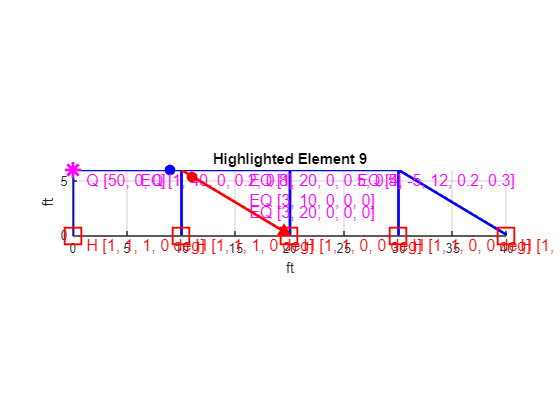


% Highlight the Element on the Structure
Graph_Highlight_Element(Element_ID, Node_Table, Element_Table, Unit, Global_Hinge, Size_Parameter, Boundary_H, Boundary_Q, Element_Q, Boundary_Movement)

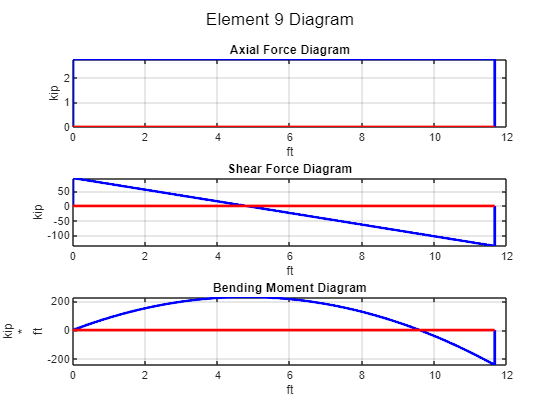

ans = 'Local Force at Element End'

ans = 'Element Force at Node 7'

Fx = 2.7542

Fy = 95.8289

Mz = 0

ans = 'Element Force at Node 3'

Fx = 2.7542

Fy = -137.4092

Mz = -242.4529


% Obtain Element Force Diagram
Element_Force_Diagram(Element_ID, Unit, U_global, Node_Table, Element_Table, Element_Property, Element_Q, 3)